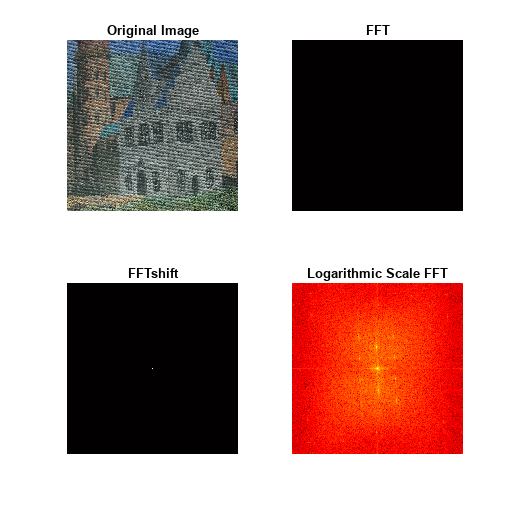

painting = imread("185-8526_IMG.JPG");
pic = im2gray(painting);
meangrayscale = mean(pic, "all");
enhanced = pic - meangrayscale;

% FFT of the pattern
Z_fft = fft2(pic);
Z_fftshift = fftshift(Z_fft);
Z_fftshift_log = log(abs(Z_fftshift) + 1);

% Plotting
figure('Position',  [200, 100, 512, 512]);
subplot(2, 2, 1); imshow(painting); axis square; title('Original Image');
subplot(2, 2, 2); imagesc(abs(Z_fft)); axis square; title('FFT'); axis off;
subplot(2, 2, 3); imagesc(abs(Z_fftshift)); axis square; title('FFTshift'); axis off;
subplot(2, 2, 4); imagesc(Z_fftshift_log); axis square; title('Logarithmic Scale FFT'); axis off;
colormap hot;

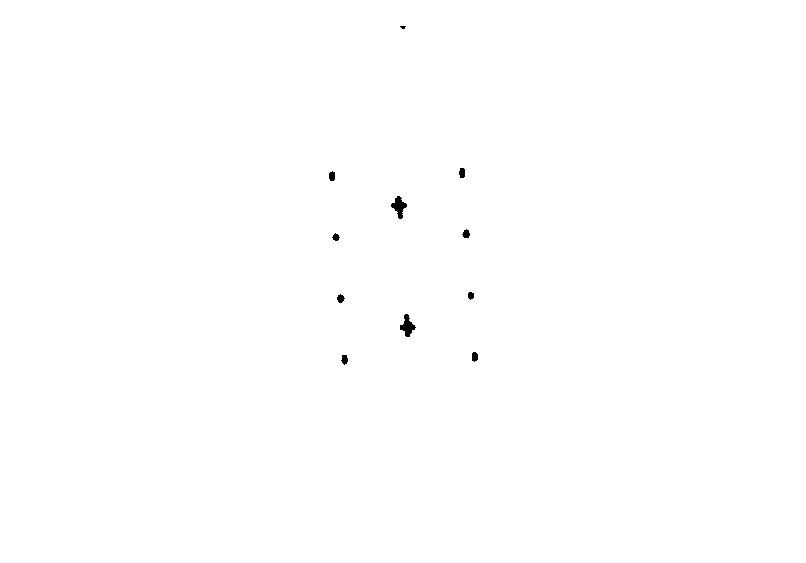

[height, width, ~] = size(painting);
if numel(size(painting)) == 2
    grayscale = painting;
else
    grayscale = rgb2gray(painting);
end

fft = fft2(grayscale);
fft_shifted = fftshift(fft);
desired = rescale(log(abs(fft_shifted + 1)), 0, 256);

maxim = max(desired(:));
[row, column] = find(desired >= maxim * 0.65);

sum = zeros(size(painting));
ignore_row_start = round(height * 0.46);
ignore_row_end = round(height * 0.54);
ignore_col_start = round(width * 0.46);
ignore_col_end = round(width * 0.54);

for i = 1:numel(column)
    if row(i) > ignore_row_start && row(i) < ignore_row_end && column(i) > ignore_col_start && column(i) < ignore_col_end
        continue;
    end
    x = column(i);
    y = row(i);
    [X, Y] = meshgrid(1:size(painting, 2), 1:size(painting, 1));
    currentval = zeros(size(painting));
    currentval(((X - x).^2 + (Y - y).^2) <= 5^2) = painting(((X - x).^2 + (Y - y).^2) <= 5^2);
    sum = sum + currentval;
end

mask = imcomplement(sum);
mask_gray = rgb2gray(mask);

% Plotting
figure;
imshow(mask_gray);

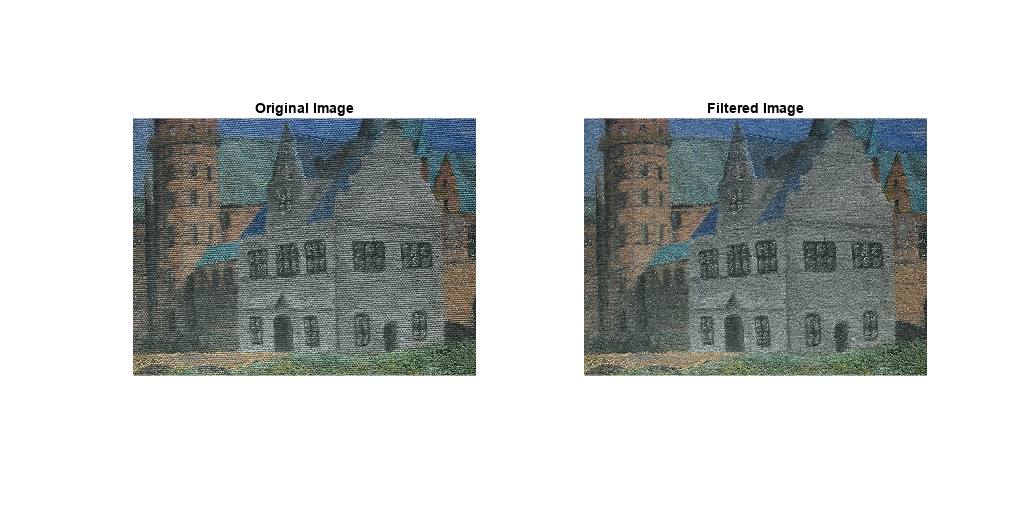

img = im2double(painting);
mask_shifted = fftshift(mask_gray);

if numel(size(img)) == 2
    pic_fft = fft2(img);
    mult = ifft2(mask_shifted .* pic_fft);
    constructed = mult;
else
    pic_red_fft = fft2(img(:, :, 1));
    pic_green_fft = fft2(img(:, :, 2));
    pic_blue_fft = fft2(img(:, :, 3));

    mult_red = ifft2(mask_shifted .* pic_red_fft);
    mult_green = ifft2(mask_shifted .* pic_green_fft);
    mult_blue = ifft2(mask_shifted .* pic_blue_fft);

    constructed = zeros(size(img));
    constructed(:, :, 1) = mult_red;
    constructed(:, :, 2) = mult_green;
    constructed(:, :, 3) = mult_blue;
end

% Plotting
figure('Position', [200, 200, 1024, 512]);
subplot(1, 2, 1);
imshow(img);
title('Original Image');
subplot(1, 2, 2);
imagesc(abs(constructed));
title('Filtered Image');
axis image;
axis off;

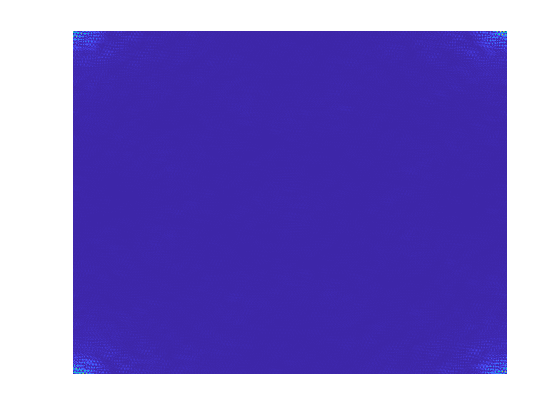

inverted_mask = imcomplement(mask_gray);
inverted_mask_fft = ifft2(fftshift(inverted_mask));
figure; imagesc(abs(inverted_mask_fft)); colormap parula; axis off;